# 第五章部分习题的MATLAB代码

5-1、5-2、5-3、5-4、5-6、5-9、5-18

## 5-4 离散系统与连续系统的频率特性

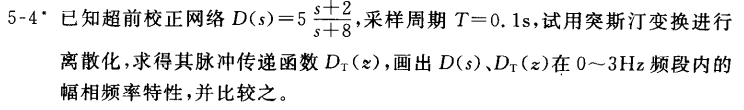

对给定系统进行离散化

T=0.1;
D=5*tf([1 2],[1 8]);
Dz=c2d(D,T,'tustin')

Dz =
 
  3.929 z - 3.214
  ---------------
    z - 0.4286
 
Sample time: 0.1 seconds
Discrete-time transfer function.



绘制0到3Hz内的幅相频率特性曲线

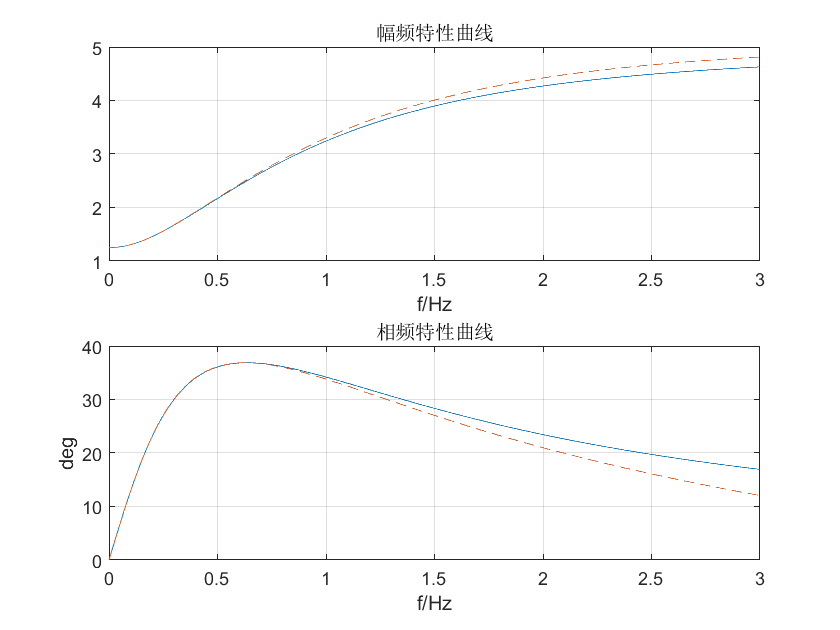

f=linspace(0,3,1000);
[mag,phase]=bode(D,f*2*pi);
[magd,phased]=bode(Dz,f*2*pi);
subplot(2,1,1);
plot(f,mag(:),'-',f,magd(:),'--');
title('幅频特性曲线');xlabel('f/Hz');
grid on;
subplot(2,1,2);
plot(f,phase(:),'-',f,phased(:),'--');
title('相频特性曲线');xlabel('f/Hz');ylabel('deg')
grid on;

## 5-9 离散系统的根轨迹

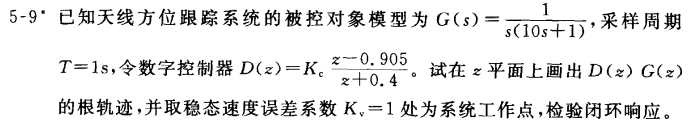

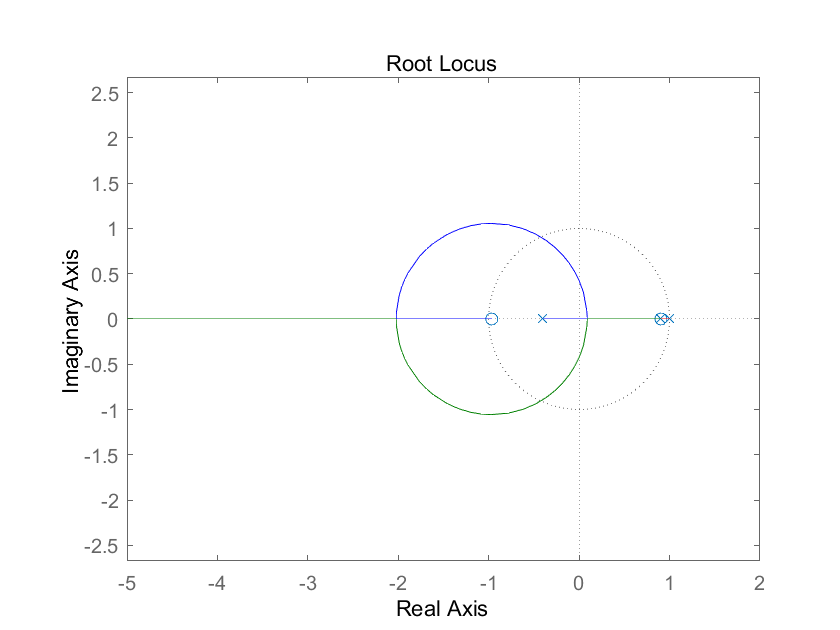

figure();
G=tf(1,conv([1 0],[10 1]));
T=1;
D0=zpk(0.905,-0.4,1,T);
Gz=c2d(G,T);
DG=series(D0,Gz);
rlocusplot(DG);%绘制开环传递函数根轨迹图
axis equal

通过计算可知速度误差系数为1时的K值,由此可以计算出对应根轨迹：


$$K_v =1=\frac{1}{T}\underset{z\to 1}{lim} \left(z-1\right)D\left(z\right)G\left(z\right)$$

$$={{\left(0.0484K_c \frac{\left(z+0.9669\right)\left(z-0.905\right)}{\left(z-0.9048\right)\left(z+0.4\right)}\right|}}_{z=1}$$


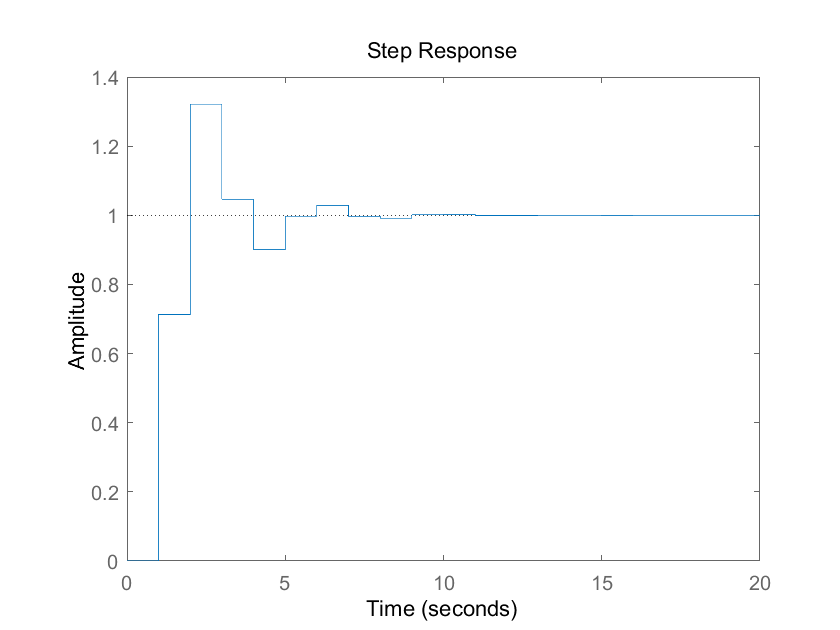

Kc=14.7372;
r=rlocus(DG,Kc);
Phi=feedback(Kc*DG,1);
stepplot(Phi)

## 5-18

该题目似乎不适合MATLAB解答